rng(0);
n = 54

n = 54

meanTEQ = 45;
sdTEQ = 7; 
empathy = round(min(max(meanTEQ + sdTEQ * randn(54,1),0),64))

empathy =     49
    58
    29
    51
    47
    36
    42
    47
    64
    64
    36
    64
    50
    45
    50


meanBrainActivity = 100;
sdBrainActivity = 10; 
brain_activity = round(meanBrainActivity + sdBrainActivity * randn(54,1))

brain_activity =    100
   115
    92
   104
    98
   111
    89
   100
   106
   111
   115
   101
    85
    93
    89


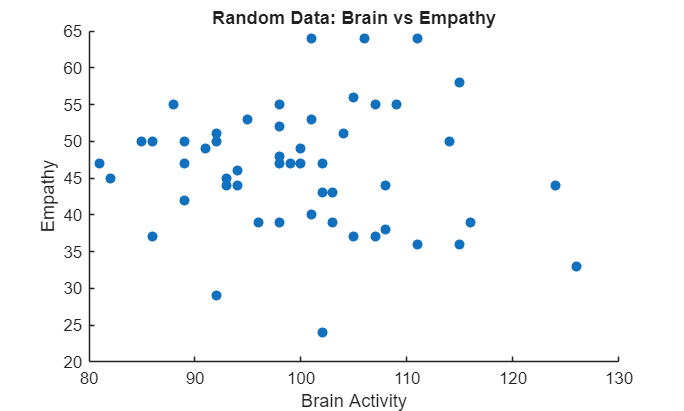


scatter(brain_activity, empathy, 'filled')
xlabel('Brain Activity')
ylabel('Empathy')
title('Random Data: Brain vs Empathy')


high_empathy = empathy >= 45;
sum(high_empathy)

ans = 32

sum(~high_empathy)

ans = 22

log_model = fitglm(brain_activity, high_empathy, 'Distribution','binomial')

log_model = Generalized linear regression model:
    logit(y) ~ 1 + x1
    Distribution = Binomial

Estimated Coefficients:
                   Estimate        SE        tStat      pValue 
                   _________    ________    _______    ________

    (Intercept)       7.2279      3.2443     2.2279    0.025889
    x1             -0.068003    0.031952    -2.1283     0.03331


54 observations, 52 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 5.17, p-value = 0.0229


predict_prob = predict(log_model, brain_activity)

predict_prob =     0.6053
    0.3561
    0.7254
    0.5388
    0.6373
    0.4206
    0.7642
    0.6053
    0.5049
    0.4206
    0.3561
    0.5889
    0.8096
    0.7117
    0.7642



classify_predict = predict_prob >= 0.5

classify_predict = 54×1 logical array
   1
   0
   1
   1
   1
   0
   1
   1
   1
   0
   0
   1
   1
   1
   1



conf_matrix = confusionmat(high_empathy, classify_predict);
accuracy = sum(classify_predict == high_empathy) / length(high_empathy);

disp(conf_matrix)

     9    13
     6    26



disp(['Accuracy = ' num2str(accuracy)])

Accuracy = 0.64815
